# Noisy Gaussian Sampled Data

## **Setting parameters Gaussian function**

a=1; % amplitude of Gaussian function
b=5*10^(-12); % center position of Gaussian function, unit in s
sigma=2.35482*0.181*10^(-12); % FWHM of Gaussian function

## Sampling Gaussian function

t=0.00001*10^(-12):0.02*10^(-12):10*10^(-12); % sampling Gaussian function


$$\begin{array}{l}
\text{ }\text{ }\mathbf{Gaussian}\text{ }\mathbf{function}\\
G=aexp\left(\frac{{\left(-t-b\right)}^2 }{2\sigma^2 }\right)
\end{array}$$


G=a.*exp((-(t-b).^(2))./(2.*(sigma.^(2))));

## Introducing noise of 10% to Gaussian function

% add noise 10%
Gnoise=G.*((rand(1,length(t))-0.5)./5); % introduce uniformly distributed random function
Gnew=G+Gnoise;

## Plotting sampled Gaussian function with 10% noise 

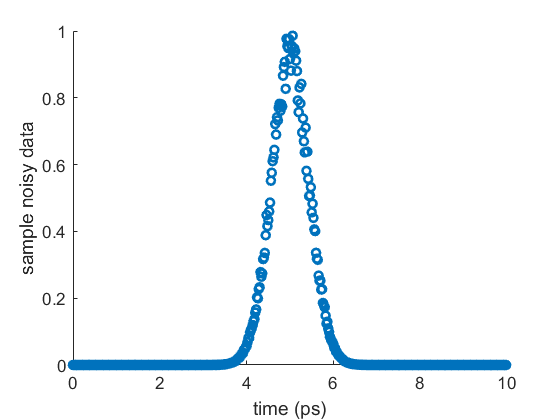

figure;
scatter(t./10^(-12),Gnew./1.068756,'Linewidth',2)
xlabel('time (ps)');ylabel('sample noisy data');set(gca,'FontSize',13);